%传统方法 实验2

%标定
% Define images to process
squareSize = 20;
imageFileName={'C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\IUInput.PNG'}

imageFileName = 1×1 cell 数组
    {'C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\IUInput.PNG'}


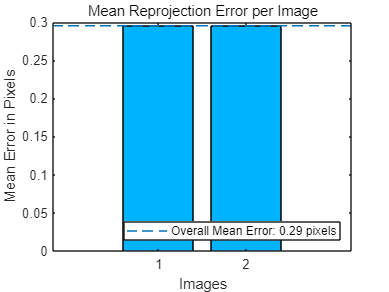

% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, ~] = detectPatternPoints(detector, imageFileName);


% Read the first image to obtain image size
originalImage = imread(imageFileName{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% load the cameraParams
load("C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\cameraParams.mat")

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

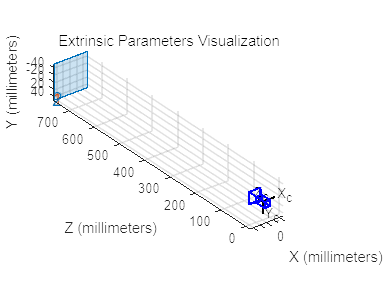


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');

%%验证重投影误差
%用world2img函数重新计算重投影点，再计算误差,注意要使用cameraParams中给的外参矩阵，而不是自己计算的外参矩阵
worldPoints3d=worldPoints;worldPoints3d(:,3)=0;%需要三维点，因此增加z轴坐标
error=zeros(length(imagePoints),1);
projectedPoints = world2img(worldPoints3d,cameraParams.PatternExtrinsics(2),cameraParams.Intrinsics,ApplyDistortion=true);
i=1;
for j=1:length(projectedPoints)
    error(j,i)=norm(projectedPoints(j,:)-imagePoints(j,:,i));
end

MeanReprojectionError=mean(error)

MeanReprojectionError = 0.2950

%结论：与cameraParams中给的重投影误差值相符

%%计算平均校准精度 
% 计算过程先将失真点校正为未失真点
error=zeros(length(imagePoints),1);
i=1;
undistortedPoints = undistortPoints(imagePoints(:,:,i),cameraParams);
newWorldPoints= img2world2d(undistortedPoints,cameraParams.PatternExtrinsics(i),cameraParams.Intrinsics);
for j=1:length(newWorldPoints)
    error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
end

MeanCalibrationError=mean(error)

MeanCalibrationError = 0.0841


%对图像进行畸变校正后再提取角点坐标
error=zeros(length(imagePoints),1);
i=1;
imOrig=imread('C:\Users\12630\Documents\MATLAB\Examples\R2023a\visionhdl\ImageUndistortHDLExample\IUInput.PNG');
[im, newOrigin] = undistortImage(imOrig, cameraParams);
detector = vision.calibration.monocular.CheckerboardDetector();
undistortedPoints = detectPatternPoints(detector, im);

newWorldPoints= img2world2d(undistortedPoints,cameraParams.PatternExtrinsics(i),cameraParams.Intrinsics);
tform = fitgeotform2d(newWorldPoints,worldPoints,"similarity");
newWorldPoints=tform.R*newWorldPoints'+tform.Translation';
newWorldPoints=newWorldPoints';
for j=1:length(newWorldPoints)
    error(j,i)=norm(worldPoints(j,:)-newWorldPoints(j,:));
end

MeanCalibrationError=mean(error)

MeanCalibrationError = 0.0872

std(error)

ans = 0.0272

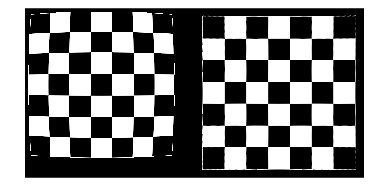

[im, newOrigin] = undistortImage(originalImage, cameraParams,OutputView="full");
imshowpair(originalImage,im,"montage")

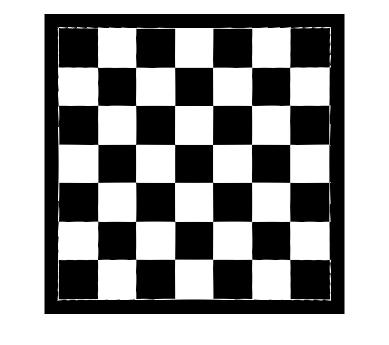

imshow(im)